# 4.4 控制程序流程的其他常用指令

## 4.4.1 程序计时tic/toc

tic `和` toc `是一对用于计时的`MATLAB`指令，你需要将`tic`和`toc`分别放在需要计时的代码段的前面和后面，运行代码后`MATLAB`就会输出这段代码的运行时长，单位为秒。`

“tic”和“toc”的英文发音简单易记，便于用户使用。

这两个词的发音分别为“tick”和“tock”，与时钟的滴答声相似

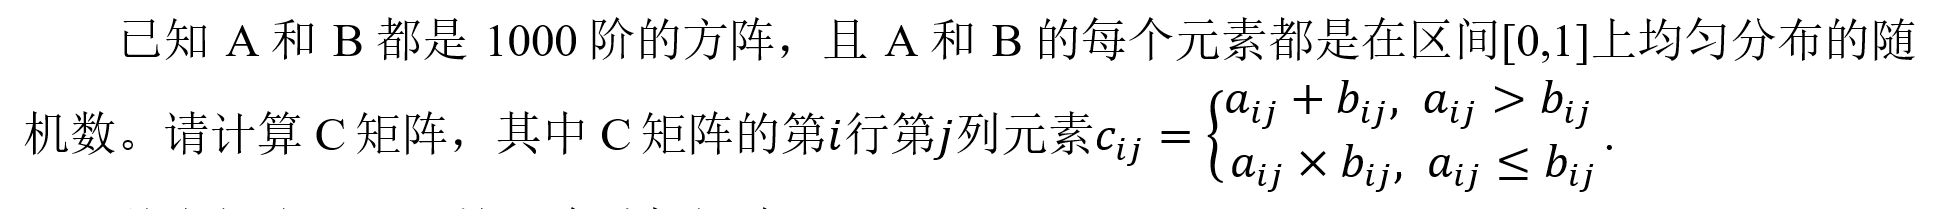

clear;clc
% 创建两个相同大小的矩阵
n = 1000;
A = rand(n, n);
B = rand(n, n);

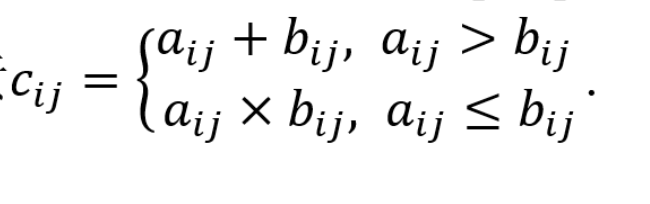

% 方法1：使用循环逐个元素相加
tic
C1 = zeros(n,n);  % 初始化最后的计算结果，这样能提高运行的效率
% 你可以注释掉上一行看看运行时长，最上方有一个clear清除了工作区，此时C1没有被初始化
for i = 1:n
    for j = 1:n
        if A(i, j) > B(i, j)
            C1(i, j) = A(i, j) + B(i, j);
        else
            C1(i, j) = A(i, j) * B(i, j);
        end
    end
end
toc
% 方法2：使用矩阵运算
tic
C2 = (A > B).*(A+B) + (A <= B).*(A.*B);
toc

检验两个结果是否相等

all(all(C1 == C2))

如果考虑浮点数计算的误差，可以怎么写代码？

all(all(abs(C1 - C2)<=1e-10))

## 4.4.2 暂停程序pause

1+2
pause
2+3

每隔0.5秒在屏幕上输出一个[1,10]上的随机整数，若输出的整数恰好为10，则停止输出。

while 1
    % 生成一个区间[1,10]上的随机整数
    x = randi([1,10],1);
    disp(x)  % 输出x
    pause(0.5)  % 暂停0.5秒
    % 判断结果是否为10，若为10则退出循环
    if x == 10
        break
    end
end

     3
     1
     1
     3
     3
     2
     5
     4
     5
    10


绘制动态爱心

% 创建一个图形窗口
figure('Color','w')
% 主循环，模拟动画
for t = 0:0.01:2*pi
    % 计算爱心形状的坐标点
    x = 16 * sin(t) .^ 3;
    y = 13 * cos(t) - 5 * cos(2*t) - 2 * cos(3*t) - cos(4*t);
    % 绘制爱心
    plot(x, y, '.r', 'LineWidth', 2);
    hold on
    axis([-20 20 -20 20]);  % 设置坐标轴范围
    axis off
    % 暂停一小段时间
    pause(0.0001);
end
hold off

## 4.4.3 用户输入数据input

`（`1`）用户输入圆的半径，然后计算圆的面积。`

r = input('请输入圆的半径：');

高版本MATLAB的提示文本也可以是字符串（用双引号包起来）

% r = input("请输入圆的半径：");  % 较低版本的MATLAB会报错

如果你的版本较低，例如2017a版本，则只能使用字符向量（用单引号包起来），使用字符串会出现如下的错误：

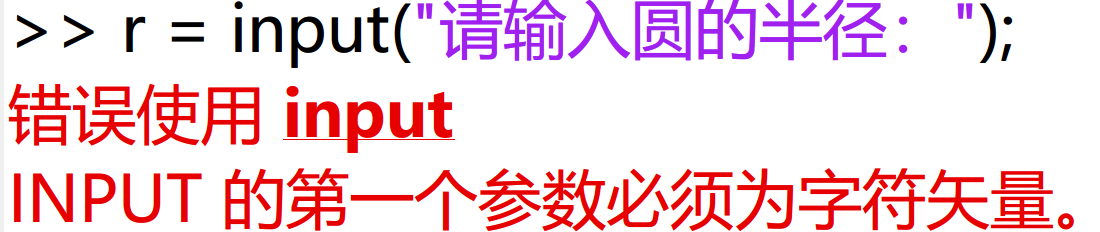

area = pi*r*r

a = input('请输入常数 a：');
b = input('请输入常数 b：');
% 下面的ss是一个文本，因此这里加上了第二个输入参数's'
ss = input('请输入操作（乘法、加法）：', 's'); 
% 根据用户输入的操作执行相应的计算
if strcmp(ss, '乘法') % strcmp函数比较字符向量是否相同
    result = a * b;
elseif strcmp(ss, '加法')
    result = a + b;
else
    result = [ ];
end
disp(result)


clear;clc
x1 = input('请输入一个字符向量：')  % 不带's'时输入字符向量需要自己添加单引号

x2 = input('请输入一个字符向量：', 's') % 带's'后输入字符向量不用添加单引号了


#### 4.4.4 显示警告信息warning

warning on  % 默认是打开的
A = [3 6; 4 8];
% 计算A的逆矩阵
inv(A)

奇异：行列式等于0

det(A)

warning off
A = [3 6; 4 8];
% 计算A的逆矩阵
inv(A)

warning on  % 重新开启警告功能
a = input('请输入常数 a：');
b = input('请输入常数 b：');
if b == 0
    warning('分母不应为0')
end
c = a/b

#### 4.4.5 显示错误信息error

a = input('请输入常数 a：');
b = input('请输入常数 b：');
if b == 0
    error('分母不应为0')
end
c = a/b

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)